# Attitude stabilization of an Underactuated Rigid Spacecraft

 This project focuses on the specific problem addressed in the 1991 paper by Byrnes and Isidori

- C. I. Byrnes and A. Isidori, ”On the Attitude Stabilization of Rigid Spacecraft,” Automatica, vol. 27, no. 1, pp. 87-95, 1991

regarding the long-standing question of whether a smooth (continuously differentiable) state feedback law can locally asymptotically stabilize a rigid spacecraft equipped with only two independent controls (e.g., in a scenario where one of its thrusters has failed) about a desired reference attitude. 

A key, and perhaps non-intuitive, result in nonlinear control is that while such underactuated systems might be locally reachable (meaning they can be steered to any nearby state) and locally asymptotically null controllable (meaning they can be steered to the origin or a target state), they may not be stabilizable by smooth feedback. The paper by Byrnes and Isidori explores this limitation.

 As an alternative to stabilization to a fixed equilibrium point, which may not be feasible, the concept of stabilizing motion around an ”attractor” (such as a limit cycle or a specific trajectory) is introduced. The paper specifically investigates driving the spacecraft to a revolute motion (a steady spin) about one of its principal axes.

The preliminar theoretical results involve the class of control systems of the type:


$$\dot{x_1 } =f_{1\;} \left(x_1 ,x_2 \right)\;x_1 +\sum_{i=1}^m b_i \;u_i$$
      
$${x_{1\;,\;} \;b}_i \in R^{n_1 }$$



$$\dot{x_2 } =f_{2\;} \left(x_1 ,x_2 \right)\;$$
      
$$x_{2\;} \in R^{n_2 }$$


evolving on $R^{n_1 +n_2 } ,$ and keeping these 3 properties:

- H1: the vector field $f\left(x\right)=\left\lbrack \begin{array}{c}
f_1 \left(x\right)\\
f_2 \left(x\right)
\end{array}\right\rbrack ,\;\textrm{with}\;\;x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \in R^{n_1 +n_2 }$ is smooth and $f\left(0\right)=0;$

- H2: $f_2 \;\left(x_1 ,x_2 \right)=0\;$ implies $x_1 =0;$

- H3: $\textrm{rank}\;\left(\frac{\delta \;f_2 }{\delta \;x_1 }\left(0\right)\right)=n_2$.

A profound outcome of their analysis (Theorem 3) is the established equivalence for the class of systems under consideration: local asymptotic stabilization by smooth feedback is possible if, and only if, the system can be linearized by smooth coordinate changes and feedback transformations. This provides a powerful analytical tool; if a system within this class cannot be feedback linearized, it cannot be smoothly stabilized to an equilibrium. This has significant practical implications, guiding engineers away from futile attempts at smooth stabilization and towards alternative control objectives.

In particular, when point stabilization is proven impossible or impractical, stabilizing the system to a desired motion or a bounded region -an attractor- becomes a valuable engineering alternative. The proposed method is a constructive approach to achieving such behavior, overcoming as control objective the simple equilibrium regulation. If a system cannot be held perfectly still, ensuring its motion is predictable, bounded, and perhaps even useful (like a steady spin for a spacecraft) is a valid and often necessary engineering goal.

Let us start considering the general expression of the dynamics of the system on the state manifold $M=\textrm{SO}\left(3\right)\times \;R^3$, taking as state variables the orientation and angular velocity pair $\left(R,\omega \right)$:


$$J\dot{\omega} =S\left(\omega \right)\;J\omega +\sum_{i=1}^m b_i \;u_i$$
      
$$b_i \in R^3$$



$$\begin{array}{l}
\dot{R} =S\left(\omega \right)\;R\;\;\;\;\;\;\;\;\;\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


Where J is the inertia matrix of the rigid spacecraft and $S\left(\omega \right)$ is the skew-symmetric matrix representing the cross product $b\to b\times \omega \ldotp$

Choosing the Euler angles parameter $\phi ,\;\vartheta ,\;\psi$ to represent the rotation around the reference frame $R,$ and expressing the inertia terms w.r.t the principal axes, it is possible to obtain the form:


$$\left\lbrack \begin{array}{c}
{\dot{\omega} }_1 \\
{\dot{\omega} }_2 \\
{\dot{\omega} }_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
a_1 \;\omega_2 \;\omega_3 \\
a_2 \;\omega_1 \;\omega_3 \\
a_3 \;\omega_1 \;\omega_2 
\end{array}\right\rbrack \;$$

$$+\sum_{i=1}^m b_i \;u_i$$
 


$$\left\lbrack \begin{array}{c}
\dot{\phi} \\
\dot{\vartheta} \\
\dot{\psi} 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{ccc}
\cos \vartheta  & 0 & \sin \vartheta \\
\sin \vartheta \;\tan \phi  & 1 & -\cos \vartheta \;\tan \phi \\
-\sin \vartheta \;\sec \phi  & 0 & \cos \vartheta \;\sec \phi 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
\;\omega_1 \;\\
\;\omega_2 \;\\
\;\omega_3 \;
\end{array}\right\rbrack$$


That is evident to belong to the class of non linear system discussed before. For this kind of control system, it is proved in the paper that the two following theorems hold:

## Theorem 1. 

For the specified class of system, there is a continuously differentiable feedback law, $u_i =F_i \;\left(x\right)$ , rendering the origin locally asymptotically stable if, and only if,

 
$$m^{\prime } =n_{1\ldotp }$$


## Theorem 2. 

For the specified class of system, If there is a continuously differentiable static or dynamic state feedback law rendering the origin locally asymptotically stable, then $m^{\prime } =n_{1\ldotp }$

with $m^{\prime } =\dim \;\left\lbrace \textrm{span}\;\left\lbrace b_{1,\;} \;\ldotp \ldotp \ldotp b_m \right\rbrace \right\rbrace$.

Since for the spacecraft underactuated model holds that $n_1 =3,{\;m}^{\prime } =2,$ it is possible to find out the following corollary:

## Corollary 1. 

A rigid satellite with (one or) two independent actuators can not be locally asymptotically stabilized using continuously differentiable static or dynamic state feedback.

It is necessary to shift our control objective: in particular, from the stabilization of a fixed equilibrium point to the stabilization about a revolute motion, i.e. the attractor

$\Lambda =\left\lbrace \left(\omega_i ,\;\phi ,\vartheta ,\psi \right):\left(\omega_i =0\;,\;\phi =\vartheta =0\right)\right\rbrace$, for $i=1,2\ldotp$ 

So the goal it to design a control law able to stabilize at  least a particular subset of the overall dynamic equations: since that the revolute motion around which we would like to stabilize the system will be the one around the $\psi$ axis, the dynamic equation describing the evolution of that Euler parameter won't be necessarly asymptotically stablized. 

Let us come back to the general formulation of the problem, adding 2 new hypothesis on the existence of particular output functions:

$\exists \;y_i =h_{i\;} \left(x\right)\;\;\;\;i=1,\ldotp \ldotp \ldotp ,m$ smooth functions defined in a neighbourhood of  $x=0\;$s.t.:

- 
$$h_i \;\left(0\right)=0\;\;\textrm{for}\;i=1,\ldotp \ldotp \ldotp ,m\;;$$


- the matrix $A\left(x\right)=\left\lbrace a_{\textrm{ij}} \;\left(x\right)\right\rbrace =\left\lbrace \frac{\delta \;h_i }{\delta \;x}\;g_j \left(x\right)\right\rbrace$ is non singulare at $x=0\ldotp$

Then, follwing the general procedure proposed in the Isidori and Byrnes' paper, It is possible to performe a smooth coordinates transformation for the original system

$\left(z,y\right)=\left(z_1 ,\;\ldotp \ldotp \ldotp z_{n-m} \;,y_1 \;,\ldotp \ldotp \ldotp ,y_m \right)$ s.t. in the new coordinates we obtain the normal form:


$$\begin{array}{l}
\dot{z} =f_{1\;} \left(z,y\right)\;+g_1 \;\left(z,y\right)\;u\\
\dot{y} =f_2 \;\left(z,y\right)+g_2 \;\left(z,y\right)\;u
\end{array}$$


with $f_1 \;\left(0,0\right)=0,\;f_{2\;} \left(0,0\right)=0$ and $g_2 \;\left(z,y\right)$ non singular at all $\left(z,y\right)\;\;\textrm{near}\;\left(0,0\right)$.

We can now choose as control action a feedback law of the form:


$$u=g_2^{-1} \;\left(z,y\right)\;\left\lbrack -y-f_2 \;\left(z,y\right)\right\rbrack$$


to put the system in the form


$$\begin{array}{l}
\dot{z} ={\tilde{f} }_{1\;} \left(z,y\right)\;+{\tilde{g} }_1 \;\left(z,y\right)\;y\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\dot{y} =-y
\end{array}$$


with ${\tilde{f} }_{1\;} \left(z,y\right)=f_1 \;\left(z,y\right)-g_1 \left(z,y\right)\;$$g_2^{-1} \;\left(z,y\right)\;\;\left\lbrack -f_2 \;\left(z,y\right)\right\rbrack ,\;\;\;\;\;$${\tilde{g} }_1 \;\left(z,y\right)=\;$$-g_1 \left(z,y\right)$ $g_2^{-1} \;\left(z,y\right)\;\;\ldotp$

The idea behind a control action of this form is to render the set $Z=\left\lbrace \;x:h_i \left(x\right)=0;\;i=1,\ldotp \ldotp \ldotp ,m\right\rbrace$an invariant manifold for the normal form system. $Z$is the set in which the system evolves like its zero dynamics, i. e. the residual dynamics of the system forcing the output identically equal to zero:


$$\dot{z} ={\tilde{f} }_{1\;} \left(z,0\right)\;$$


properly addressed as  is "a local description of the behaviour of the control system under the constraint $h_i \left(x\right)=0$.

The overall idea is to design suitable dummy output functions $h_i \;\left(x\right)$ s.t. they solve the invariance equations for the existence of a Centre Manifold that has to be exhibited by the system, thanks to which prove the stability of the control loop under the feedback law $u$. To do this, it is sufficient to investigate and prove the stability of the Reduced Dynamics obtained imposing the system to evolve around that Centre Manifold.

Note that it is possibile to do this thanks to the fact that, after the coordinates transformation and the feedback effect, the dynamics associated to $y$ is surely stable.

The following statement is crucial for this described goal.

## Theorem 6. 

Consider a system of the specified form satisfying  (H1)-(H5). Suppose, in addition, that:

- H(6) the constrained dynamics on $h_i \;\left(x\right)$ has an  asymptotically stable equilibrium at $z=0\ldotp$ 

Then, the control law $u$ locally stabilizes the normal form system at $\left(z,y\right)=\left(0,0\right)$. 

In the paper are proposed 3 different derivations of controllers based on these theoretical results, all involving the spacecraft case:

-  first attempt of designing $h_i \;\left(x\right)$ neglecting the kinematics equations, and considering $\;a_3 =1,\;a_2 =a_1 =0$ in the model;

- the second one including the kinematics, but also $\;a_3 =1,\;a_2 =a_1 =0$;

- the third one, whose resulting controller is the content of Theorem 4, including the overall system (dynamics + kynematics equations) and different values of $\;a_3 \not= 0,\;a_2 \not= a_1 \not= 0\ldotp$

Here are instead performed simulations on this described cases, evaluating the evolutions of system's states variable both in normal form and in the original form for all presented situations.

## Simulation 1. Simplified system without Euler's angles dynamics.


$$\left(\;a_3 =1,\;a_2 =a_1 =0\right)$$


The designed output functions are:


$$\begin{array}{l}
h_1 \;\left(\omega_1 \;,\omega_2 ,\omega_3 \right)={-\omega }_1 -\omega_3 \\
\;h_2 \;\left(\omega_1 \;,\omega_2 ,\omega_3 \right)={-\omega }_2 +\omega_3^2 
\end{array}$$


And the expressions for the components of the stabilizing controller of the form $u$ are: 

clc
clear all
close all


syms y1 y2 w1 w2 w3

% control inputs in normal form

u1_n = - (-y1 + ((-w3^3) + w3*y2 -  (w3^2)*y1 + y1*y2))

$$u1\_n = {w_{3}}^{3}+y_{1}\,{w_{3}}^{2}-y_{2}\,w_{3}+y_{1}-y_{1}\,y_{2}$$

u2_n = - (-y2+  2*w3*((-w3^3) + w3*y2 -  (w3^2)*y1 + y1*y2))

$$u2\_n = y_{2}-2\,w_{3}\,\left(-{w_{3}}^{3}-y_{1}\,{w_{3}}^{2}+y_{2}\,w_{3}+y_{1}\,y_{2}\right)$$

% control inputs in original coordinates

u1  = eval(subs(u1_n,[y1, y2], [-w1-w3, -w2+(w3)^2]))

$$u1 = {w_{3}}^{3}-w_{3}-{w_{3}}^{2}\,\left(w_{1}+w_{3}\right)-\left(w_{2}-{w_{3}}^{2}\right)\,\left(w_{1}+w_{3}\right)-w_{1}+w_{3}\,\left(w_{2}-{w_{3}}^{2}\right)$$

u2 = eval(subs(u2_n,[y1, y2], [-w1-w3, -w2+(w3)^2]))

$$u2 = {w_{3}}^{2}-2\,w_{3}\,\left({w_{3}}^{2}\,\left(w_{1}+w_{3}\right)+\left(w_{2}-{w_{3}}^{2}\right)\,\left(w_{1}+w_{3}\right)-{w_{3}}^{3}-w_{3}\,\left(w_{2}-{w_{3}}^{2}\right)\right)-w_{2}$$

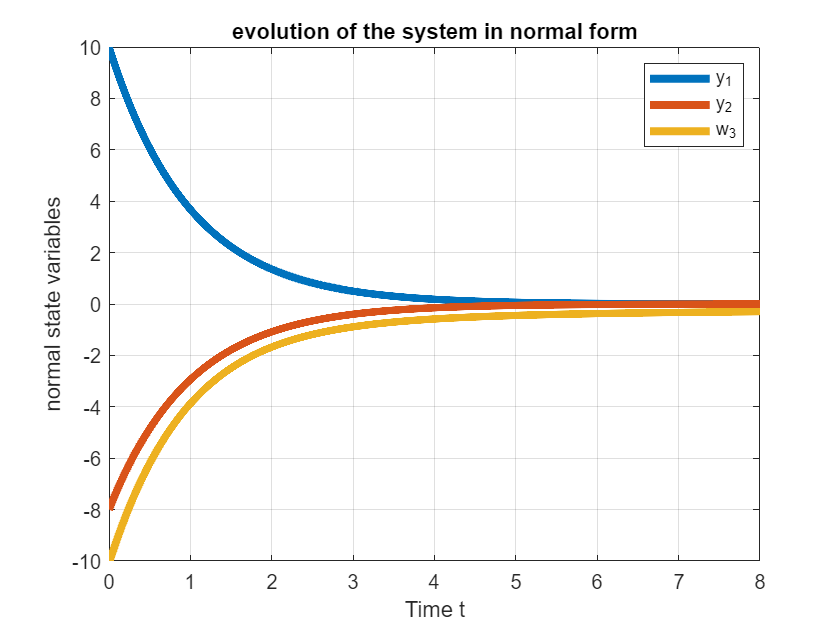


% half simplified dynamics


y1_0 = 10;
y2_0 = -8;
w3_0 = -10;
t= 0: 0.001:8;
Y0 = [y1_0; y2_0; w3_0];

% normal form simulation

[t,y1] = ode45(@closed_loop_1_nf,t,Y0);

figure()
plot(t,y1(:,1),t,y1(:,2), t, y1(:,3), 'LineWidth',4), grid on
title('evolution of the system in normal form');
xlabel('Time t');
ylabel('normal state variables');
legend('y_1','y_2', 'w_3');

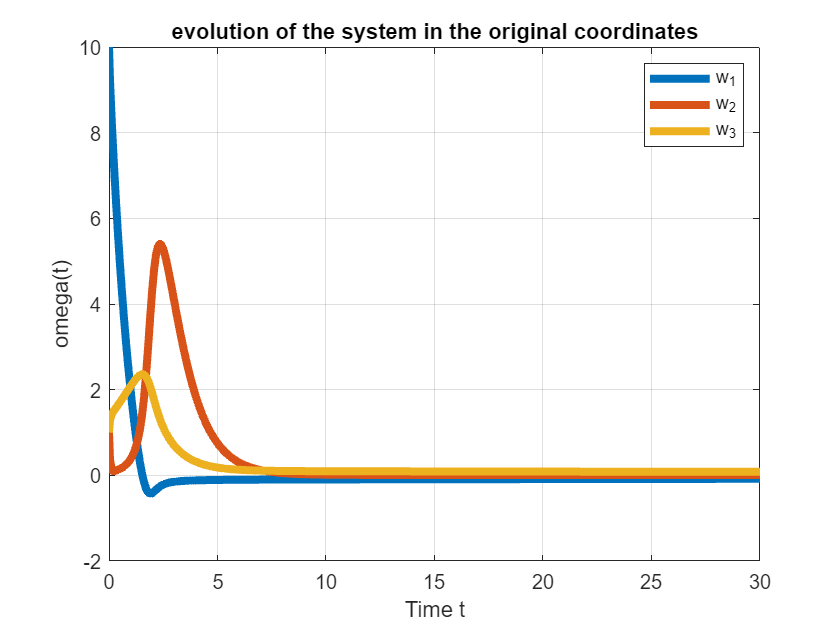

% original coordinates simulation

w1_0 = 10;
w2_0 = 1;
w3_0 = 1;
t= 0: 0.001:30;
W0 = [w1_0; w2_0; w3_0];

[t,y2] = ode45(@closed_loop_1,t,W0);

figure()
plot(t,y2(:,1),t,y2(:,2), t, y2(:,3), 'LineWidth',4), grid on
title('evolution of the system in the original coordinates');
xlabel('Time t');
ylabel('omega(t)');
legend('w_1','w_2', 'w_3');

First two simulations confirm what we expected: the existence of a steady state and the convergence of all state variables to the origin, thanks to the fact we designed $h_i \;\left(x\right)$ neglecting the kinematics part.

## Simulation 2: Simplified system with complete dynamics.


$$\left(\;a_3 =1,\;a_2 =a_1 =0\right)$$



$$\begin{array}{l}
h_1 \;\left(\omega_1 \;,\omega_2 ,\omega_3 \right)=-\left(\omega_{1\;} +\phi +A_1 \;\omega_3 +B_1 \;\omega_3^2 \right)\\
\;h_2 \;\left(\omega_1 \;,\omega_2 ,\omega_3 \right)=-\left(\omega_{2\;} +\vartheta +A_2 \;\omega_3 +B_2 \;\omega_3^2 \right)
\end{array}$$


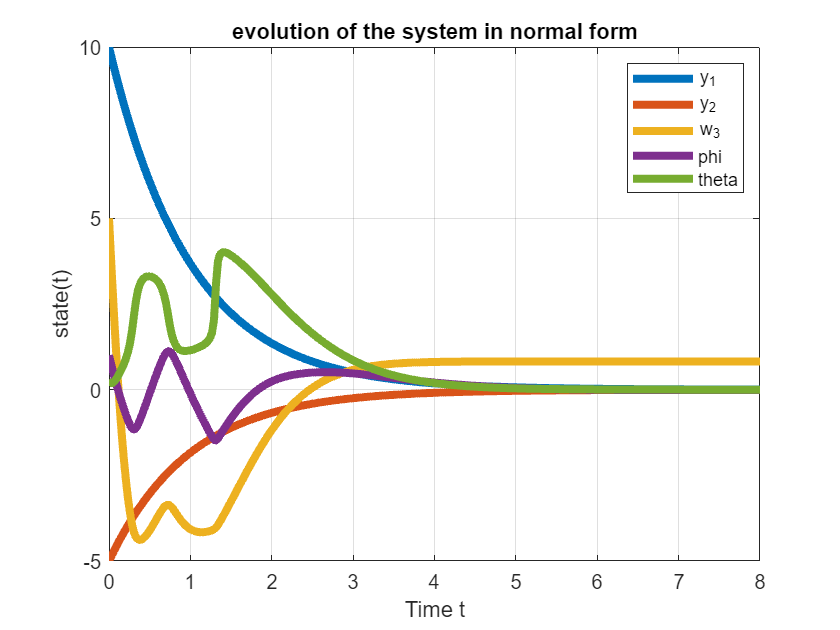

% normal form simulation

y1_0 = 10;
y2_0 = -5;
w3_0 = 5;
phi_0 = 1;
theta_0 = 0.3;
psi_0 = 1;

t= 0: 0.0001:8;
WA0 = [y1_0; y2_0; w3_0; phi_0; theta_0; psi_0];

[t,y3] = ode45(@closed_loop_2_nf,t,WA0);

figure()
plot(t,y3(:,1),t,y3(:,2), t, y3(:,3), t, y3(:,4), t, y3(:,5), 'LineWidth',4), grid on
title('evolution of the system in normal form');
xlabel('Time t');
ylabel('state(t)');
legend('y_1','y_2', 'w_3', 'phi', 'theta', 'Location' ,'northeast');

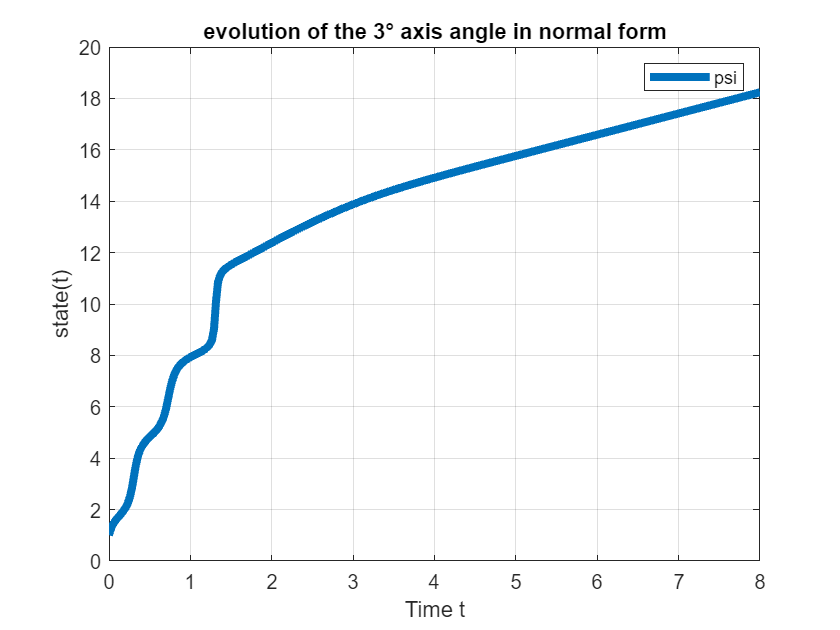

figure()
plot(t, y3(:,6), 'LineWidth',4), grid on
title('evolution of the 3° axis angle in normal form');
xlabel('Time t');
ylabel('state(t)');
legend('psi');

The results exhibits something more than before: including the kinematics equations in the design of $h_i \;\left(x\right)$, we reach the secondary control goal claimed before, i.e. the stabilization of a portion of the system state variables around an attractor, namely in the spacecraft's case a steady state revolute motion about the axis associated to the $\psi$ Euler angle.

Note that the instability of the $\psi$dynamics, proved in the paper and better shown below, does not have any correlation with the stability of the Residual Dynamics obtained investigating the evolution of the system on the Centre Manifold defined by $h_i \;\left(x\right),$ this is because the $\psi$is not even taken into account in the synthesis of the stabilizing controller, and that Euler's parameter is completely out of the control loop.

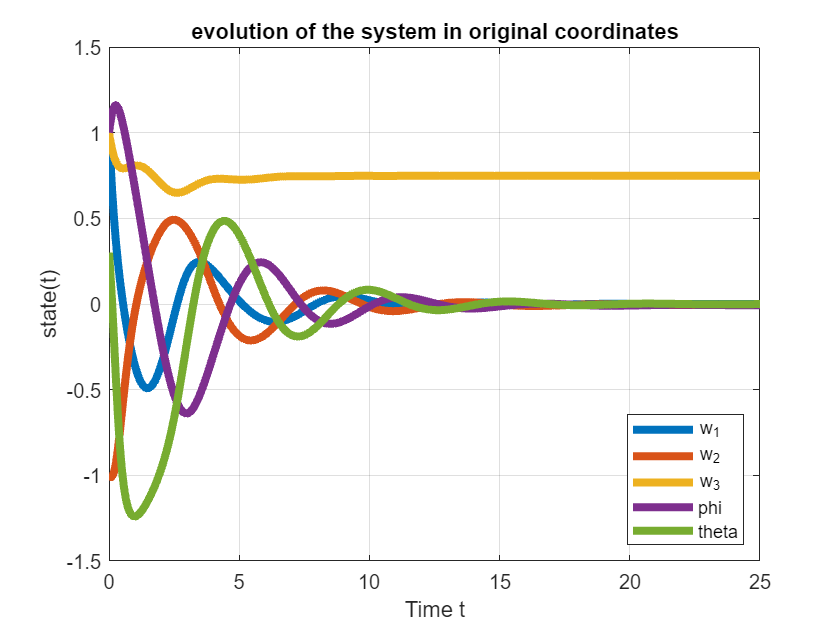

% original coordinates simulation

w1_0 = 1;
w2_0 = -1;
w3_0 = 1;
phi_0 = 1;
theta_0 = 0.3;
psi_0 = 1;

t= 0: 0.0001:25;
WA0 = [w1_0; w2_0; w3_0; phi_0; theta_0; psi_0];

[t,y4] = ode45(@closed_loop_2,t,WA0);

figure()
plot(t,y4(:,1),t,y4(:,2), t, y4(:,3), t, y4(:,4), t, y4(:,5), 'LineWidth',4), grid on
title('evolution of the system in original coordinates');
xlabel('Time t');
ylabel('state(t)');
legend('w_1','w_2', 'w_3', 'phi', 'theta', 'Location' ,'Southeast');

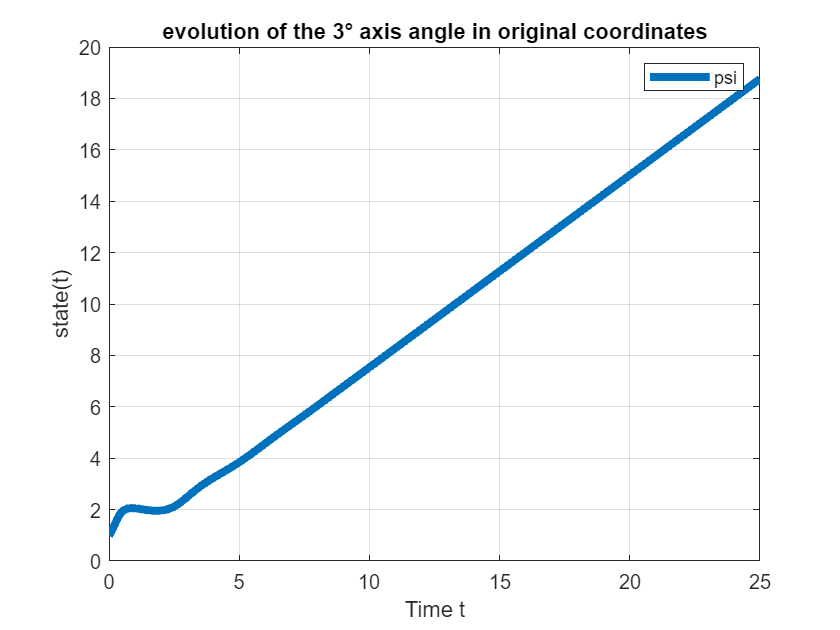

figure()
plot(t, y4(:,6), 'LineWidth',4), grid on
title('evolution of the 3° axis angle in original coordinates');
xlabel('Time t');
ylabel('state(t)');
legend('psi');

In original coordinates it is more evident the overall behavior including the development of the transient.

## Simulation 3: Overall underactuated system 


$$\left(\;a_3 \not= 1,\;a_2 \not= a_1 \not= 0\right)$$


The formalization of the result about the stabilizing controller of the overall dynamics has been stated in Theorem 4.

## Theorem 4.

Consider a rigid satellite with two actuators aligned along the first two principal axes. The feedback control law 


$$\left\lbrace \begin{array}{ll}
\;u_1 =-a_1 {\;\omega }_2 {\;\omega }_3 -\omega_1 -\phi -A_1 {\;\omega }_{3\;} -B_1 {{{\;\omega }_3 }^2 -{\;\omega }_1 \;\cos \left(\theta \right)-\omega_1 \;\sin \left(\theta \right)-A_1 {\;a}_{3\;} \omega_1 {\;\omega }_2 -2\;B_1 \;a_3 \;\omega_1 {\;\omega }_2 {\;\omega }_3 }  & \\
u_2 =-a_2 {\;\omega }_1 {\;\omega }_3 -\omega_2 -\theta -A_2 {\;\omega }_{3\;} -B_2 {{{\;\omega }_3 }^2 -{\;\omega }_1 \;\sin \left(\theta \right)\;\tan \left(\phi \right)-\omega_2 -\omega_{3\;} \;\cos \left(\theta \right)\;\tan \left(\phi \right)-A_2 {\;a}_{3\;} \omega_1 {\;\omega }_2 -2\;B_1 \;a_3 \;\omega_1 {\;\omega }_2 {\;\omega }_3 }  & 
\end{array}\right.$$


where:


$$\left\lbrace \begin{array}{ll}
A_1 \;A_{2\;} =0 & \\
a_{3\;} \left(A_1 \;\left(A_1 -B_2 \right)\right)-A_2 \left(A_2 -B_1 \right)<0 & 
\end{array}\right.$$


locally asymptotically stabilizes the rigid satallite underactuated model about a revolute motion about the third principal axis.

Note that these two conditions has be verified also in the first two cases.

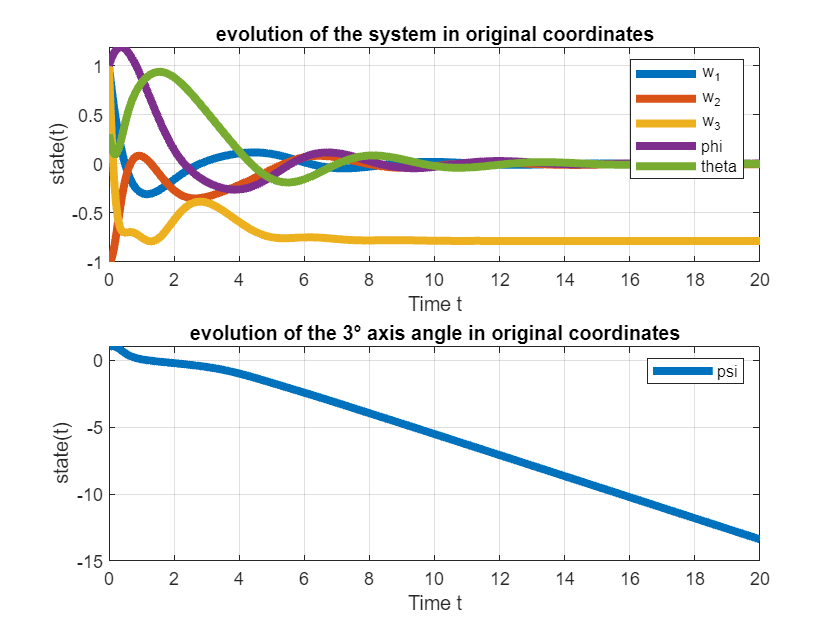

% original coordinates simulation

a3 = 10;
a2 = 5;
a1 = 12;

w1_0 = 1;
w2_0 = -1;
w3_0 = 1;
phi_0 = 1;
theta_0 = 0.3;
psi_0 = 1;

t= 0: 0.0001:20;
WA0 = [w1_0; w2_0; w3_0; phi_0; theta_0; psi_0];

[t,y4] = ode45(@closed_loop_3,t,WA0);

figure()

subplot(211)
plot(t,y4(:,1),t,y4(:,2), t, y4(:,3), t, y4(:,4), t, y4(:,5), 'LineWidth',4), grid on
title('evolution of the system in original coordinates');
xlabel('Time t');
ylabel('state(t)');
legend('w_1','w_2', 'w_3', 'phi', 'theta', 'Location' ,'Northeast');

subplot(212)
plot(t, y4(:,6), 'LineWidth',4), grid on
title('evolution of the 3° axis angle in original coordinates');
xlabel('Time t');
ylabel('state(t)');
legend('psi');

The last plot confirms what Theorem 7 states, i.e. that is not possible to stabilize a rigid spacecraft with just two actuators around a point of the equilibrium one-dimentional manifold $\Lambda$, where also the angle associated to the 3° axis is costant and stops to rotate with angular velocity $\omega_3 =0\ldotp$  

As before, the actual evolution of the angular velocity $\omega_3$ reach a costant steady state different from zero, and consequently the parameters $\psi$contiues to evolve, exhibiting unstable behaviors of its dynamics.

The resulting behavior is a steady state spin around $\psi \ldotp$

## Theorem 7. 

There is no smooth state feedback law,  having closed-loop equilibrium $\Lambda$,  robustly stabilizing a rigid satellite using two gas-jet actuators, where $\Lambda$ is the one-dimentional manifold $\Lambda =\left\lbrace \;\left(\omega_{i\;} ,\;\phi ,\;\theta \;,\;\psi \right):\omega_i =0,\;\phi =\theta =0\right\rbrace \;\textrm{with}\;i=1,2,3$.

Here it is proposed a grafical simulation about the behavior of the controlled system with the feedback law derived before.

We can see that the attitude evolution is identically the one we expected: a transient in which all Euler's parameters varies, until arriving to a steady state condition in which the only parameter that continue to vary is $\psi ,$ the one associated to the unstable dynamics. 

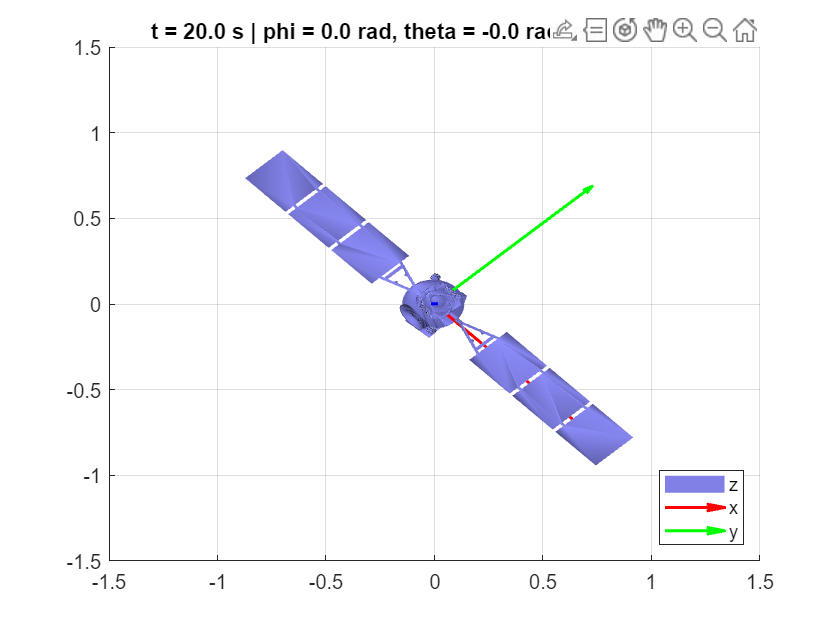

visualize_spacecraft(t, y4)   % ZXZ Euler rotation

function dydt = closed_loop_1_nf(t,y)

Y = [y(1) ; y(2)];

f1 = -y(3)^3 + y(3)*y(2) - (y(3)^2)*y(1) + y(1)*y(2);

f2a= - (-y(3)^3 + y(3)*y(2) - (y(3)^2)*y(1) + y(1)*y(2)) ;
f2b =  -2*y(3)*(-y(3)^3 + y(3)*y(2) - (y(3)^2)*y(1) + y(1)*y(2));

f2= [f2a; f2b];

g2 = [-1, 0;0,-1];

u = inv(g2)* (-Y - f2);


dydt = [f2a - u(1); f2b - u(2); f1];
end

function dydt = closed_loop_1(t,y)

u1 = (y(3)^3) - y(3) - (y(3)^2)*(y(1) + y(3)) - (y(2) -( y(3)^2))*(y(1) + y(3)) - y(1) + y(3)*(y(2) - (y(3)^2));
u2 =  (y(3)^2 )- 2*y(3)* ( (y(3)^2)  * (y(1) + y(3))  + (y(2) - (y(3)^2))  *(y(1) + y(3)) -(y(3)^3) - y(3)* (y(2) - (y(3)^2)) ) - y(2);

u = [u1; u2];


dydt = [u(1); u(2); y(1)*y(2)];
end

function dydt = closed_loop_2_nf(t,y)

A1 = 0;
A2 = 0.005;
B1 = 0.01;    % A1* A2 = 0
B2 = 0.02;    % A1(A1-B2) - A2(A2+B1) < 0

Y = [y(1) ; y(2)];

f1 = y(4) + (A1*y(3)) + (B1*(y(3)^2));
f2 = y(5) + (A2*y(3)) + (B2*(y(3)^2));


w3d = (f1*f2) + (f1*y(2)) + (f2*y(1))+ (y(1)*y(2));

fid = cos(y(5))* (-y(1)-f1) + sin(y(5))* y(3);

thetad =  (sin(y(5))* tan(y(4))* (-y(1)-f1))- (cos(y(5))* tan(y(4))* y(3)) + (-y(2) -f2);

psid = - (sin(y(5))* sec(y(4))* (-y(1)- f1)) + (cos(y(5))* y(3)* sec(y(4)));

f1d= -(fid+ ((A1+ (2*B1*y(3))) * w3d));
f2d = -(thetad + ((A2+ (2*B2*y(3))) * w3d));

F2= [f1d; f2d];

F1 = [w3d; fid; thetad; psid];

g2_inv = [-1, 0;0,-1];

u = g2_inv * (-Y - F2);

y1d = -u(1)+ F2(1);
y2d = -u(2) + F2(2);

dydt = [y1d; y2d; F1(1); F1(2); F1(3); F1(4)];
end

function dydt = closed_loop_2(t,y)

A1 = 0;
A2 = 0.005;
B1 = 0.01;    % A1* A2 = 0
B2 = 0.02;    % A1(A1-B2) - A2(A2+B1) < 0


u1 = -y(1)- y(4) - A1*y(3) - B1*(y(3)^2) - y(1)*(cos(y(5))) - y(1)*(sin(y(5))) - A1*(y(1)*y(2)) - (2*B1 * y(1)*y(2)*y(3));

u2 = -y(2)- y(5) - A2*y(3) - B2*(y(3)^2) - (y(1)*(sin(y(5)) * tan(y(4))))- y(2) -(y(3)*cos(y(5))*tan(y(4))) -  - A2*(y(1)*y(2)) - (2*B2 * y(1)*y(2)*y(3));


w3d = y(1)* y(2);

fid = (cos(y(5))* (y(1))) + (sin(y(5))* y(3));

thetad =  (sin(y(5))* tan(y(4))* (y(1)))  - (cos(y(5))* tan(y(4))* y(3)) + (y(2));

psid = - (sin(y(5))* sec(y(4))* (y(1))) + (cos(y(5))* y(3)* sec(y(4)));


F1 = [w3d; fid; thetad; psid];

u = [u1; u2];

y1d = u(1);
y2d = u(2) ;

dydt = [y1d; y2d; F1(1); F1(2); F1(3); F1(4)];
end


function dydt = closed_loop_3(t,y)

a3 = 10;
a2 = 5;
a1 = 12;

A1 = 0.01;
A2 = 0;
B1 = 0.01;    % A1* A2 = 0
B2 = 0.02;    % a3* A1(A1-B2) - A2(A2+B1) < 0


u1 = - (a1 * y(2) * y(3)) -y(1)- y(4) - A1*y(3) - B1*(y(3)^2) - y(1)*(cos(y(5))) - y(1)*(sin(y(5))) - A1*(y(1)*y(2)) - (2*B1 * y(1)*y(2)*y(3));

u2 = -(a2* y(1)* y(3)) -y(2)- y(5) - A2*y(3) - B2*(y(3)^2) - (y(1)*(sin(y(5)) * tan(y(4))))- y(2) -(y(3)*cos(y(5))*tan(y(4))) -  - A2*(y(1)*y(2)) - (2*B2 * y(1)*y(2)*y(3));


w3d = a3* y(1)* y(2);

fid = (cos(y(5))* (y(1))) + (sin(y(5))* y(3));

thetad =  (sin(y(5))* tan(y(4))* (y(1)))  - (cos(y(5))* tan(y(4))* y(3)) + (y(2));

psid = - (sin(y(5))* sec(y(4))* (y(1))) + (cos(y(5))* y(3)* sec(y(4)));


F1 = [w3d; fid; thetad; psid];

u = [u1; u2];

y1d = (a1 * y(2) * y(3)) + u(1);
y2d =(a2 * y(1) * y(3)) + u(2) ;

dydt = [y1d; y2d; F1(1); F1(2); F1(3); F1(4)];
end


function visualize_spacecraft(t, state)
figure;
axis manual;
grid on
xlabel('X'); ylabel('Y'); zlabel('Z');
hold on
view(3)
hold on
xlim([-1.5 1.5]); ylim([-1.5 1.5]); zlim([-1.5 1.5]);


spacecraft = stlread('Chandra\chandra.stl');

faces = spacecraft.ConnectivityList;
vertices = spacecraft.Points;

vertices = vertices - mean(vertices);

scaleFactor = 0.0007; 
vertices = vertices * scaleFactor;


for i = 1:500:length(t)
    xlim([-1.5 1.5]); ylim([-1.5 1.5]); zlim([-1.5 1.5]);
    clf
    yaw   = state(i,4);  % phi
    pitch = state(i,5);  % theta
    roll  = state(i,6);  % psi

 
    R = eul2rotm([yaw, pitch, roll], 'ZXZ');
    v_rotated = (R * vertices')';  

    patch('Vertices', v_rotated, 'Faces', faces, ...
          'FaceColor', [0.5 0.5 0.9], 'EdgeColor', 'none', 'FaceAlpha', 1); grid

    lighting gouraud
    camlight headlight
    material dull
    hold on;
    
    % Axes
    
    quiver3(0, 0, 0, R(1,1), R(2,1), R(3,1), 1.0, 'r', 'LineWidth', 1.5); % Z
    hold on
    quiver3(0, 0, 0, R(1,2), R(2,2), R(3,2), 1.0, 'g', 'LineWidth', 1.5); % X
    hold on
    quiver3(0, 0, 0, R(1,3), R(2,3), R(3,3), 1.0, 'b', 'LineWidth', 1.5); % Z

    xlim([-1.5 1.5]); ylim([-1.5 1.5]); zlim([-1.5 1.5]);
    axis manual;

    legend('z','x', 'y', 'Location' ,'Southeast');

    title(sprintf('t = %.1f s | phi = %.1f rad, theta = %.1f rad, psi = %.1f rad', ...
        t(i), yaw, pitch, roll));

   
    drawnow;

end
end